# Simple simulation for matlab code and simulink comparison

2026/04/28 Peter Chang

## Using a for loop to run stepwise time step simulation (not real)

% clear and reset all to prepare for standard difference method
% demonstration of x = x+ dt

Standard difference method $\frac{dx(t)}{dt} = ax(t)$, with a given initial condition $x(t_o) = x_0$.

Solving this standard equation results in a "theoratical solution".

$x(t) = x_0 e^{at}$, and this is an expoenetial decay standard plot.

### How do we do it with "numerical simulation" ?

Standard difference method, Newton's method is applicable to find this linear equation....

$\frac{dx(t)}{dt} = \lim\limits_{\Delta t \to 0}\frac{x(t+\Delta t)-x(t)}{\Delta t}$ by replacing the left hand side of the equation... and let us run the simulation along a time

t = 0;      % 起始時間 後面被改成 t = 0:10;
dt = 0.1;   % 間隔時間
tend = 10;  % 結束模擬時間

% remember to use initial condition, and with x(t=0) = 3.5
x_ini = 3.5;


In this case we set the full equation into 

$x(t+\Delta t) = x(t) +\Delta t \left[ ax(t)\right]  $, thus assigning a iterative algorithm

$x = x + (dt * ax)$, where one in the programing needs to identify:

- x starts with x_ini = 3.5,

- dt as the time step now assigned as dt = 0.1,

- a changeable "co-efficient a" value

a = -2.25

a = -2.2500

### Compairing to theoratical solution!

In the case where all the assigned values (for simulation), there is an real solution now with our "theortical" values:

$x(t) = x_0 e^{at} = (3.5)e^{-2.25t}$, where $a = -2.25$ is the default co-efficient, and now we need to assign a t, to find the associated x.

### Iterations

nsteps = 10/dt% number of steps

nsteps = 100


x = zeros(1,nsteps);    % pre-allocate solution
t = zeros(1,nsteps);    % note re-sue vaiable "t"

x(1) = x_ini;       % step zero
t(1) = 0;

for i = 2:nsteps
    disp(i + "th step")
    x(i) = x(i-1)+dt*a*x(i-1);
    t(i) = t(i-1)+dt;
end

2th step
3th step
4th step
5th step
6th step
7th step
8th step
9th step
10th step
11th step
12th step
13th step
14th step
15th step
16th step
17th step
18th step
19th step
20th step
21th step
22th step
23th step
24th step
25th step
26th step
27th step
28th step
29th step
30th step
31th step
32th step
33th step
34th step
35th step
36th step
37th step
38th step
39th step
40th step
41th step
42th step
43th step
44th step
45th step
46th step
47th step
48th step
49th step
50th step
51th step
52th step
53th step
54th step
55th step
56th step
57th step
58th step
59th step
60th step
61th step
62th step
63th step
64th step
65th step
66th step
67th step
68th step
69th step
70th step
71th step
72th step
73th step
74th step
75th step
76th step
77th step
78th step
79th step
80th step
81th step
82th step
83th step
84th step
85th step
86th step
87th step
88th step
89th step
90th step
91th step
92th step
93th step
94th step
95th step
96th step
97th step
98th step
99th step
100th step


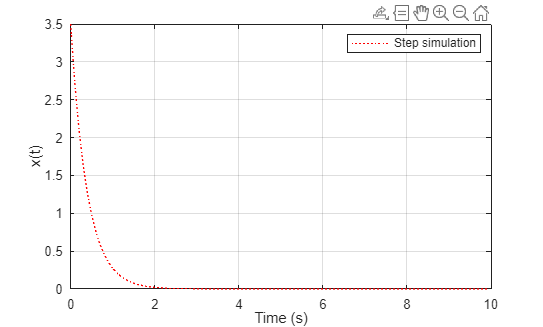


plot(t,x, Color = "r", LineStyle = ":", MarkerSize = 10)
grid on;
xlabel("Time (s)")
ylabel("x(t)")
legend("Step simulation")
hold on;

## Direct matrix solution for theoratical plot

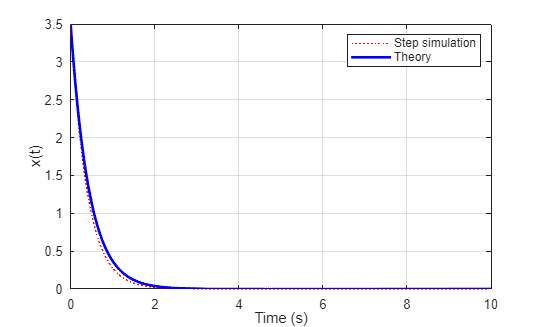

tt = 0:0.0001:10;  % theoratical time, can be different from t step-wise
xx = x_ini*exp(a.*tt);
plot(tt,xx, Color = "b", LineWidth = 2);
legend("Step simulation","Theory")

### Transforming theoratical solutions to multiple step-wise iterative through Laplace Transform

This is a simple input-output system that is a integrator, where $\mathcal{L}[\dot{x}] = sX+x(0)$, with $\mathcal{L}[x(t)] = X(s)$

So we can make a block of output/input as Transfer Function:$\frac{Y(s)}{U(s)}=G(s)$, and now the full $\frac{dx(t)}{dt} = ax(t)$ differential equation is simply $\dot{x} = ax$, and if we take the whole Laplace transform $\mathcal{L}\left[ \dot{x} = ax \right] $, we end up with

$sX+x(0) = aX$, then 

### Using Simulink to run the input-output senario

we now turn to open the following .slx file for a simple demonstration

click here